# 案例：随机圆里产生随机点

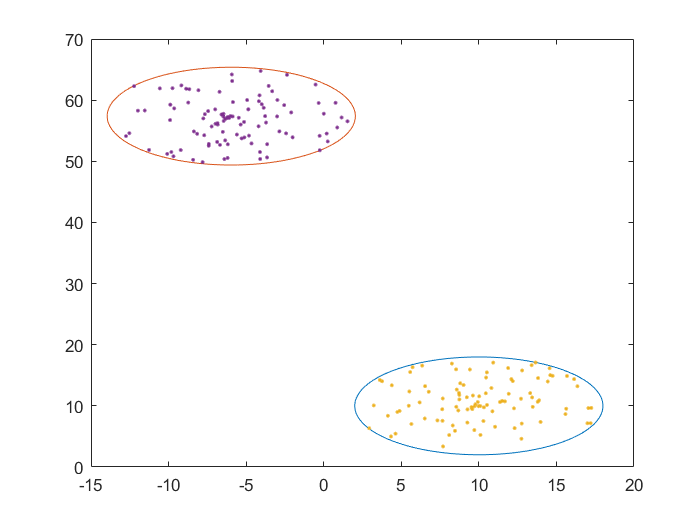

clear;clc;
% 半径
r = 8;
% 圆心距
d = 50;
% 圆 1 的坐标，可变
ox1 = 10;
oy1 = 10;
% 圆 2 的坐标，可变，那就随机吧
theta_r = rand*2*pi;
ox2 = ox1 + d*cos(theta_r);
oy2 = oy1 + d*sin(theta_r);
% 用极坐标形式，毫无疑问
theta = linspace(0, 2*pi, 100);
% 圆坐标
x1 = ox1 + r*cos(theta);
y1 = oy1 + r*sin(theta);
x2 = ox2 + r*cos(theta);
y2 = oy2 + r*sin(theta);
% 画图
plot(x1, y1, x2, y2);
count = 100;
% 散点位置
% 随机半径
rs1 = rand(1, count)*r;
% 随机角度
thetas1 = rand(1, count)*2*pi;
% 确定坐标
xs1 = ox1 + rs1 .* cos(thetas1);
ys1 = oy1 + rs1 .* sin(thetas1);
% 同样来一遍
rs2 = rand(1, count)*r;
thetas2 = rand(1, count)*2*pi;
xs2 = ox2 + rs1 .* cos(thetas2);
ys2 = oy2 + rs1 .* sin(thetas2);
% 画图
hold on
plot(xs1, ys1, '.');
plot(xs2, ys2, '.');
hold off